## **Starting Our Own FMCW Radar Model**

### Defining a CHIRP

Do you remember the first image I showed you of what a radar system looks like in general?

Where you could see a transmitter, a transmitted signal and an object... Well, let's start by describing the signal we want to launch into space.

Take your time and look at the following image in detail.

This will be the function that we will describe in matlab.

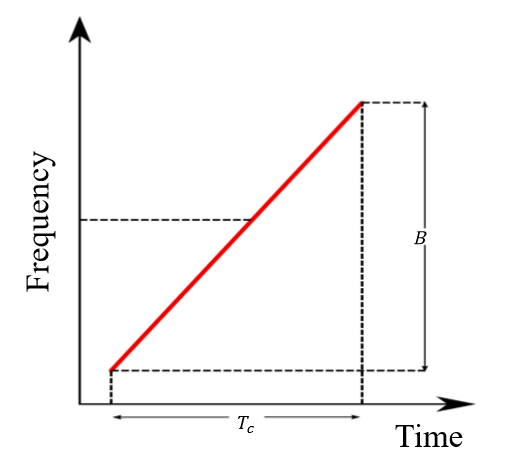

- This function describes the radars that use **FMCW** ( **F**requency **M**odulated **C**ontinuous **W**ave)

- Along the **x-axis** you can see the **Time**. 

- Along the **y-axis** you can see the **Frequency**.

- You can see that** the more time passes, the higher the frequency of our signal**. 

- But it's not randomly higher, but proportional to the time!!

- That's why you see a straight line with a **Slope**.

- Which is defined as follows: $\textrm{Slope}=\frac{\textrm{Frequency}}{\textrm{Time}}=\frac{B}{\mathrm{Tc}}$

- Now, the amount of frequency our signal increased is shown in the picture with the letter **B**. 

- This letter **B** describes our **Bandwidth**.

- On the other hand the letter **Tc **describes **how long our signal lasts**. (Here we use **c** as index to represent **C**hirp)

- The **smaller** the **Tc**, the **shorter** our **observation time**....likewise, the **larger** the **Tc**, the **longer** our **observation time**.

Another parameter we have to consider is the frequency at which we start.

That is when that red line crosses the y-axis

In the image you can't see it clearly but if you extend the signal we could say that it starts from 0.

However in practice we will want to use a starting Frequency of 6 GHz or 77 Ghz. (Just keep that in mind)

This starting point frequency is called **Carrier Frequency**.

By the way I forgot to mention....The only thing that is changing in our signal is the Frequency and nothing else!!!!

The** Amplitude and Phase shift **stay the** same all the time**.

Therefore the name **Frequency Modulated **Continuous Wave.

## Finding a Chirp Function

As a next step we have to find a mathematical function that does exactly what we are looking for. 

That is, create a function that increases its frequency the more time passes.

If you do your google homework correctly you will find the following function:


$$\mathrm{Frequency}\;\mathrm{Modulated}\;\mathrm{Signal}={\;\;\;\;\;\;\;e}^{j\left(2\pi \cdot \mathrm{fc}\cdot t\;+\pi \cdot \frac{B}{\mathrm{Tc}}t^2 \right)}$$


- *fc* - Carrier Frequency

- *t *- Time

- *B* - Bandwidth

- *Tc* - Chirp Time

## Plotting our Chirp Signal

Let's put everything we have into code and see if our equation works!

**Setting up the Chirp Parameters**

Carrier_Frequency      = 6e9;                               %Carrier Frequency in [Hz]
c                      = 3e8;                               %Speed of light in [m/s]
Chirp_Duration         = 10e-6;                             %This would be my Tc in [s]
Bandwidth              = 50e6;                              %Basically how much increase the frequency (in this case from 6GHz to 6.05 GHz)
Sweep_Slope            = Bandwidth/Chirp_Duration;          %How much increment the frequency with time

**Setting up the Frequency Modulated Function**

Sampling_Frequency     =  2*Bandwidth;                                        %How many Samples do we want (Usually at least twice the Bandwidth.... Why? We want to make sure we have enouegh samples to recreate a good signal)
Sample_Time            = 1/Sampling_Frequency;                                %This determine how much will incresea the time in the x_achse (0.000001 s each time)
Num_Of_Chirps          = 1;                                                   %How many chirps do we want
Total_Measurement_Time = Num_Of_Chirps*Chirp_Duration;                        %Total amount of time while simulating
Time_Grid              = 0:Sample_Time: Total_Measurement_Time-Sample_Time;   %This setup the boundaries of the x_achse (For example from 0s to 1s: 0s, 0.0001, 0.0002, 0.0003.... 1.000s) (For the whole Measurement Time)
Chirp_Time_Grid        = 0:Sample_Time:Chirp_Duration-Sample_Time;            %Time Grid for one single Chirp

Frequency_Modulated_Signal    = exp(1i*2*pi*Carrier_Frequency*Chirp_Time_Grid +1i*pi*(Sweep_Slope).*(Chirp_Time_Grid.^2)).'; %Voila! Our modulated signal in form of a Chirp

**Plotting Frequency Modulated Signal In Time Domain**

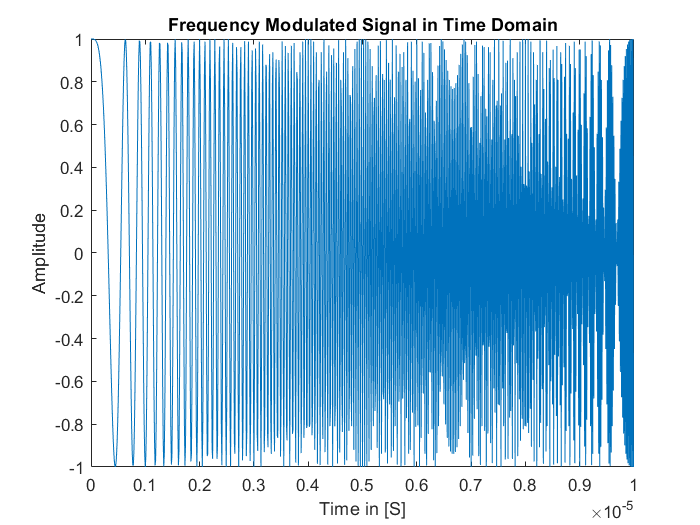

figure;
plot(Time_Grid, real(Frequency_Modulated_Signal));
title('Frequency Modulated Signal in Time Domain')
xlabel('Time in [S]');
ylabel('Amplitude');
ylim([-1.00 1])

At first glance it seems that our signal is not working as it should.

We should be able to see a signal with a **constant amplitude**, with **no phase shift **and with a **frequency that increases more and more**.

However let me tell you that what we are seeing is normal!

The reason is that when the frequency is high enough, matlab can't "keep up". Therefore when matlab connect the points of each sample it appears a little distorted.

If you don't believe me, let's take a look at the spectrogram.

**Plotting Spectogram of the Frequency Modulated Signal**

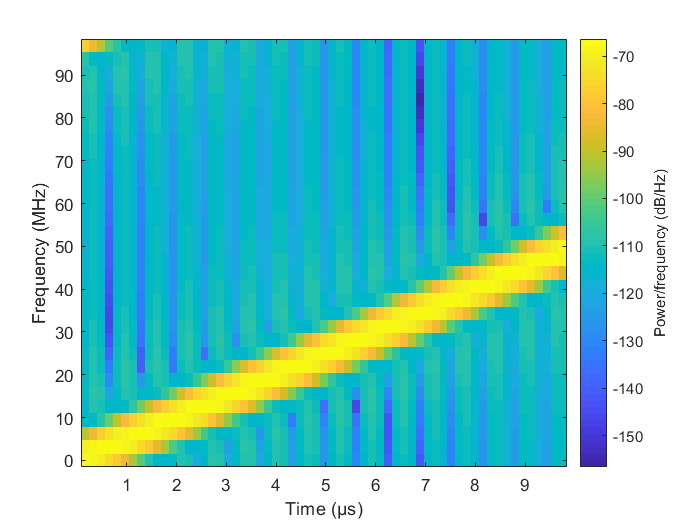

spectrogram(Frequency_Modulated_Signal,32,16,32,Sampling_Frequency, 'yaxis');

Everything seems to be in order!

There we have our Chirp!

After 10 microseconds, we increased our frequency by 50 MHz

## Transmitted and Received Chirp

Now let's see what happens when we get our signal back.

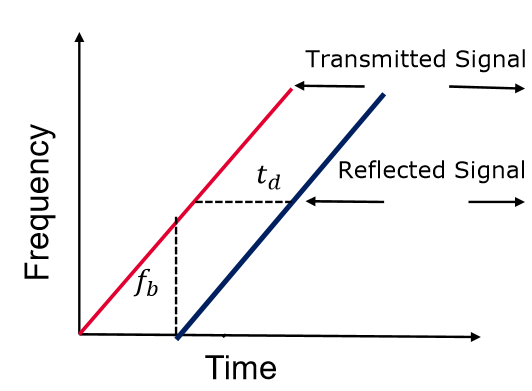

The image shows that the received signal is exactly the same as the one we sent.

The only difference is that the signal received has a certain delay. (You can see that the red line starts first)

This **delay in [s]** is shown with the symbol** td**.

From now on our objective is the following: To** find** the **Freqeuncy** **difference between the transmitted and received signal.**

This **Frequency difference in [Hz]** is shown with the symbol** fb**.

This is also known as **Beat Frequency**.

Do you remember that name? Yeah is the Frequency that I showed it to you when we saw the Frequency Spectrum for Range Estimation!

**Creating Our Target Position**

Let's start with a simple example where we only have one target.

Target1_Position = 100 ;                  %in [m]

**Creating Our Time Delay For The Received Signal**

To do this we use the following formula: $t_d =2\cdot \frac{R}{C}$

delta1 = 2*Target1_Position/c;          %in [s]

## Starting The Simulation Process

**Creating our transmitted and  received signal**

Transmitted_Signal = [Frequency_Modulated_Signal; zeros(length(Frequency_Modulated_Signal), 1)]; %We are adding extra zeros to our transmitted signal 

Received_Signal1 = circshift(Transmitted_Signal, find(Time_Grid>delta1, 1));                     %We are incorporating the time delay in our received signal

**Plotting The Received Transmitting Signal**

Let's take a look at our time domain signal.

The received signal should to appear with a time delay.

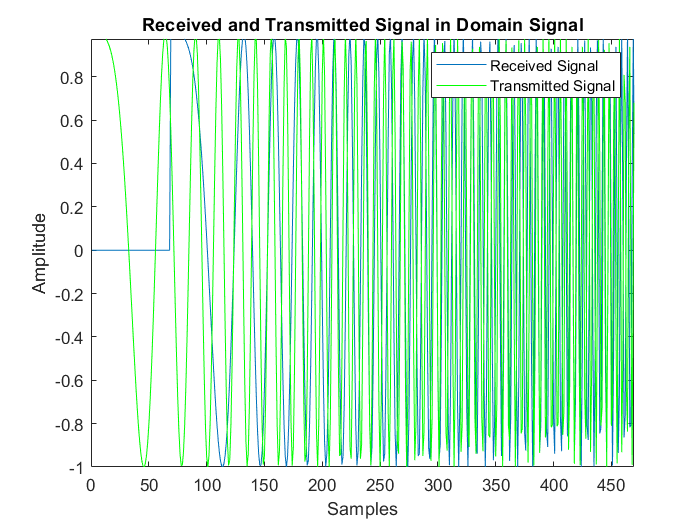

figure;
plot(real(Received_Signal1)); hold on %If you take a look at the equation we used to generate our signal.....there you notice that we use a complex number (j)....however we are just interested in the real part. Therefore the real(Received_Signal)
plot(real(Transmitted_Signal), 'g');  %The last comment applies for the transmitted signal
title('Received and Transmitted Signal in Domain Signal');
xlabel('Samples');
ylabel('Amplitude');
legend('Received Signal','Transmitted Signal');

- The green signal represents the Transmitted Signal.

- The blue signal represents the Received Signal.

- Omits the second half of the function where the amplitude is equal to 0. (I'll explain later why it looks like that)

- Right now, I want you to concentrate at the beginning of the function

- If you zoom in you can see that the blue line starts later than the green one.

- That represents the time delay!

So it looks like our code is working.

**Getting The Beat Frequency**

In case you forgot how to calculate the Beat Frequency check this image.

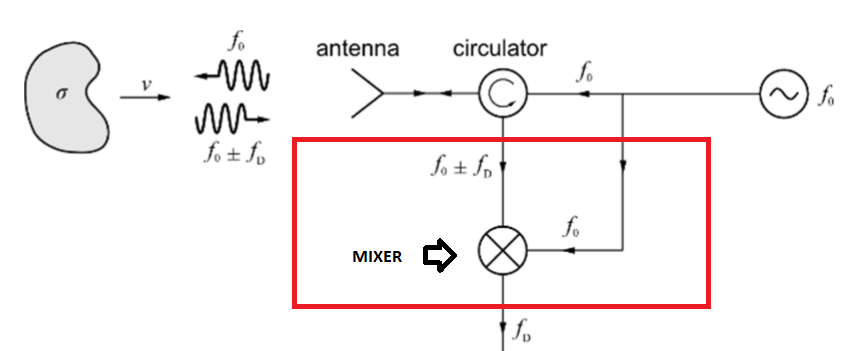

In short, we only have to multiply the transmitted signal Tx with the received signal Rx.

Beat_Frequency = Transmitted_Signal.*conj(Received_Signal1); %In order to get the Beat_Frequency we just need to do a simple multiplication! We also take the conjugated complex number of the received signal to make sure we subtract the the received signal from the transmitted signal

**Applying Fast Fourier Transform**

- The next step is to apply a **F**ast **F**ourier **T**ransform. (also known as** FFT**)

- In case you're wondering what the difference is between an FFT and a Normal Fourier Transform,** it's the number of samples**.

- If you remember, I mentioned earlier that if you take an infinite number of samples you will end up calculating a normal fourier transform.

- Well, what we want is to take a relatively small sample that will give us the necessary information we are looking for.

- That's why FFT is nothing more but a Discrete Fourier Transform.

- With the difference that it is optimized.

- This helps reduce computational stress and speed up the process.

Num_Of_Samples     = length(Time_Grid);                        %Here I am taking a number of samples equal to the signal I processed. However this value can vary depending on how accurate you want your results.
New_Num_Of_Samples = 2^nextpow2(Num_Of_Samples);               %Here I am making sure I have a sample number that is a power of 2....The reason: Improves FFT resolution
X_Time_axis        = fft(Beat_Frequency, New_Num_Of_Samples);  %The Beat_Frequency Represents the signal to which I want to apply the FFT........The New_Num_Of_Samples represents how many Samples should the FFT do

The following image shows what we just did.

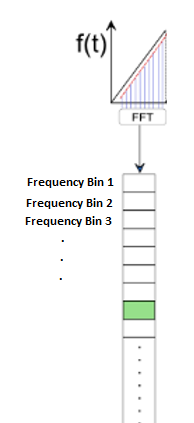

- Each of the blank boxes represents a sample of the FFT.

- Note that inside those boxes are **complex numbers**. (For example: 5 +3i)

- That means it has both a **real** and an **imaginary** part.

- You already know these boxes under the name '**' Frequency Bins**"

- The green box represents the Bin Location for our **Beat frequency**.

**Plotting The Frequency Range Spectrum**

As I mentioned, we're dealing with both imaginary and real values.

That means we have to** determine the magnitude** of our signal. $\mathrm{Magnitude}=\;\sqrt{{\mathrm{Im}}^2 +{\mathrm{Re}}^2 }$ (Just take the absolute Value)

Mag_X             = abs(X_Time_axis);                     %Absolute value for the fft

Now we have to convert our signal into **Power in dB** using the following conversion:

Power             = 20*log10(Mag_X);                      %Transform Calculated Magnitude into Power in db

Finally plotting everything.

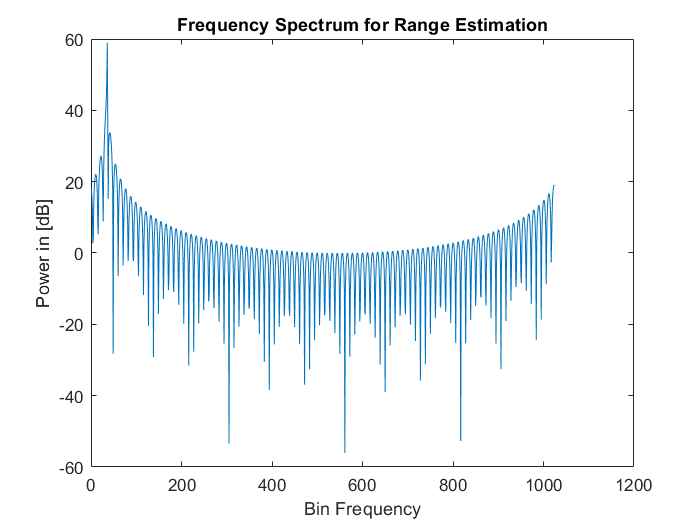

figure;
plot(Power);
title('Frequency Spectrum for Range Estimation');
xlabel('Bin Frequency');
ylabel('Power in [dB]');

**Convert Bin Frequencies into normal Frequencies**

Frequency_Bins  = 0:length(Power)-1;                               %Getting the Frerquency bins (just sample index)
Frequency_Range = Frequency_Bins*Sampling_Frequency/length(Power); %Turn those into normal Frequencies.

**Using those Frecuencias to calculate the Range**

Range =  Frequency_Range*Chirp_Duration*c/(2*Bandwidth); 

**Plotting the same one more time**

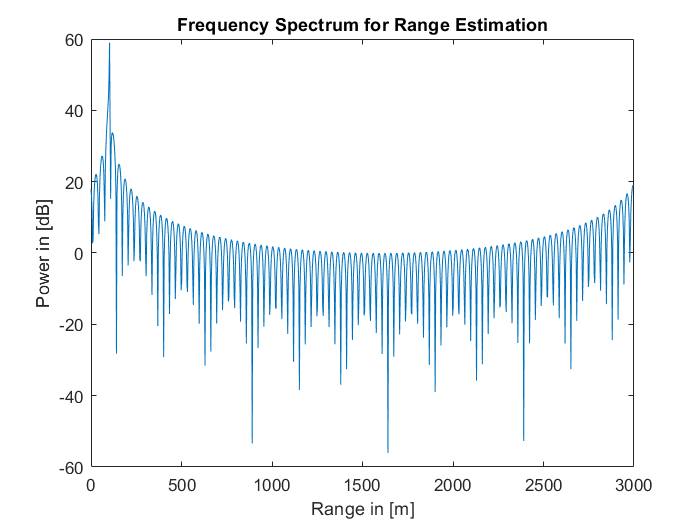

figure;
plot(Range, Power);
title('Frequency Spectrum for Range Estimation');
xlabel('Range in [m]');
ylabel('Power in [dB]');

## **Playing Instructions!**

Now it's your turn to play a little!

But first I want you to keep in mind following super formulas:


$$\mathrm{Beat}\;\mathrm{Frequency}\;\left(\mathrm{fb}\right)=\frac{\left(2R\right)}{c}\frac{\left(B\right)}{\mathrm{Tc}}$$



$$\mathrm{Delay}\;=\frac{\left(2R\right)}{c}$$



$$\mathrm{Maximum}\;\mathrm{Range}=\frac{\left(\mathrm{Tc}\cdot c\right)}{2}\cdot \frac{1}{5\ldotp 5}$$



$$\textrm{Range}\;\textrm{Resolution}=\frac{c}{2B}$$


- What would happen if.....You change the Target distance to 500 m

- What would happen if you increase the Bandwidth?

- Make sure to increase it between 300 MHz and 500 MHz.

-  What happened to the Frequency Spectrum and my **Beat Frequency**

- What would happen if you decrease the Bandwidth?

- Pick up values close to 10 MHz but not less!!

- What do you see? What happened to the Frequency Spectrum and my **Beat Frequency**?

- What if You change the target distance to 100m?

- What did just happen now with my Frequency Spectrum and** Beat Frequency**?

- Feel free to explore different target distances until you figure out what is happening.

- I want you to increase the distance to at least 1500 m

- What happened and why do we get an error?

- How can we fix it? (Hint: Think about our observation time)

## Range Estimation For Multiple Targets

Pay attention to the following image.

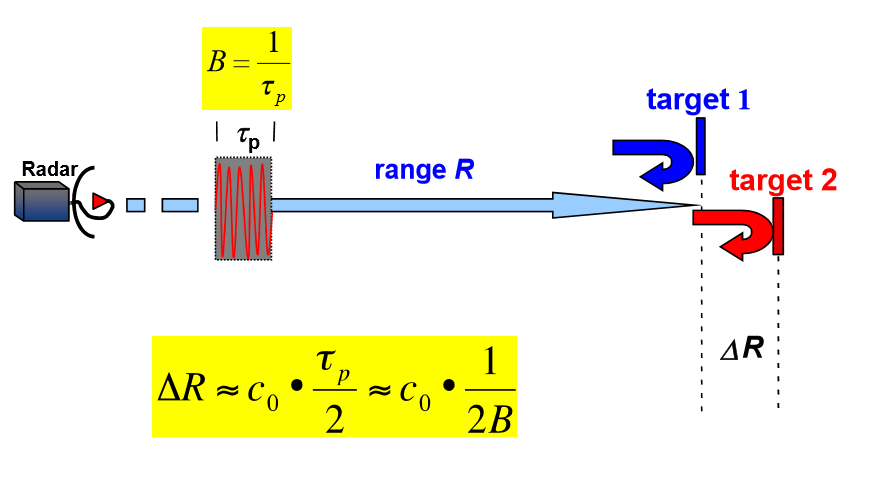

Our goal is as follows:

- To increase the number of targets and to be able to determine the position of each.

- I want to stress the **importance** of the** range resolution formula**.

- **The lower the delta R the better!**

- For that you need to i**ncrease the bandwidth**

**Creating Multiple Targets**

Here we are creating 2 more Targets.

Target1_Position = 100;  %in [m]
Target2_Position = 100;  %in [m]
%Target3_Position = 500; 

**Creating Multiple Time Delays**

We now have more targets, which means that each target has a time delay.

delta2 = 2*Target2_Position/c;  % in [s]
%delta3 = 2*Target3_Position/c; 

**Creating Multiple Received Signals Corresponding To Each Reflected Target**

Now we're getting more signals back.

Each received signal represents a target.

Received_Signal2 = circshift(Transmitted_Signal, find(Time_Grid>delta2, 1));
%Received_Signal3 = circshift(Transmitted_Signal, find(Time_Grid>delta3, 1));

Note that here we do not have to re-create one more time the transmitted signal. 

We are still transmitting a single Chirp from the last excersise.

**Adding All The Received Signals Together**

Sum_Received_Signals = Received_Signal1 + Received_Signal2;%+ Received_Signal3; %Here you have to delete the ';' after the received_Signal2

**Getting the Beat Frequencies**

Beat_Frequencies = Transmitted_Signal.*conj(Sum_Received_Signals);

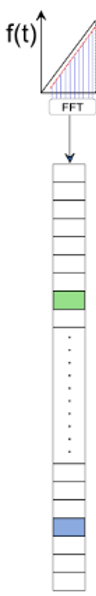

- As you can see the process is the same as before.

- Only 2 colored boxes are shown in the image. 

- However, in the case of 3 Targets we would see 3 colored boxes

- Each one representing the Frequency Bin Location

**Applying the FFT**

X_Time_axis_multiple        = fft(Beat_Frequencies, New_Num_Of_Samples); 

**Plotting the Beat Range Frequency Specrtum**

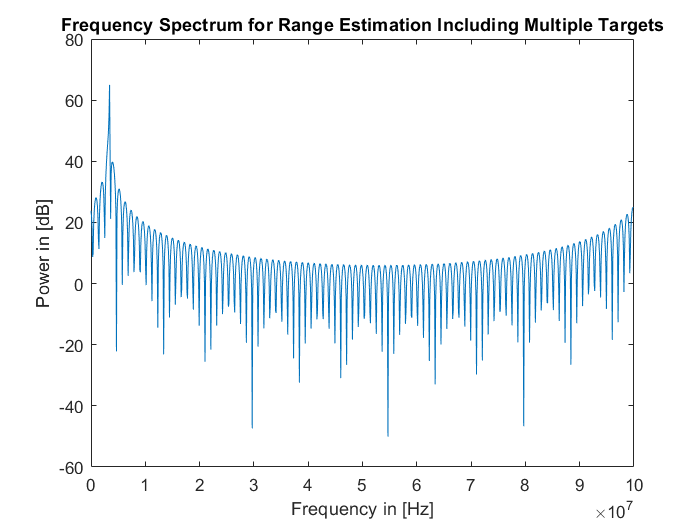

Mag_X_multiple             = abs(X_Time_axis_multiple);                     %Absolute value for the fft
Power_multiple             = 20*log10(Mag_X_multiple);                      %Transform Calculated Magnitude into Power in db

figure;
plot(Frequency_Range,Power_multiple);
title('Frequency Spectrum for Range Estimation Including Multiple Targets');
xlabel('Frequency in [Hz]');
ylabel('Power in [dB]');

This time I'm not going to show you the plot with the range conversion already. 

Instead, I invite you to use the formula yourself so yo can get familiar with it!

%Range =  (Frequency you read)*Chirp_Duration*c/(2*Bandwidth)

## Playing Instructions!

Let's play a little bit one more time!

Again, here is the super formula I want you to keep in mind:


$$\mathrm{Range}\;\mathrm{Resolution}=\frac{c}{2B}$$


I want you to do the following:

- Put the distance of the second target at the same distance as the first target.

- Plot it and tell me what you should expect to see at the Frequency Spectrum.

- Now change the distance to the second target by at least 100 meters. (For example: Target1 = 100 and target2 = 210)

- **Use the zoom tool in case you need!**

- Plot it again and tell me what do you see at the Frequency Spectrum.

- Play with distances as you like.

- Now plot the 2 targets with a difference of 2 meters between each other. (For example: target1 = 100m  and target2 =102m)

- **Use the zoom tool and zoom the peak!**

- Why do we only see one peak?

- What we can do to fix it and see the 2 peaks again. (Of course without changing the distance). (Think about the **Range Resolution Formula**!)

- Feel free to create more targets with different distances.

- You can uncomment the corresponding lines in order to create a third target.